# Exercise 3

**Sinewave**

[t, X] = ode45(@odefun_sine,[0 40],[0 0]);
x = -X(:,1);
v = -X(:,2); 
omega = 1/10*2*pi;
h0 = 0.5; % amplitude [m]
h = sin(omega.*t)*h0;

grid on
plot(t,x+h+1,t,h)
title('x position as when ground is a sine shape')
legend('Biker','Ground')
xlabel('time [s]')
ylabel('x [m]')
grid on

**Step**

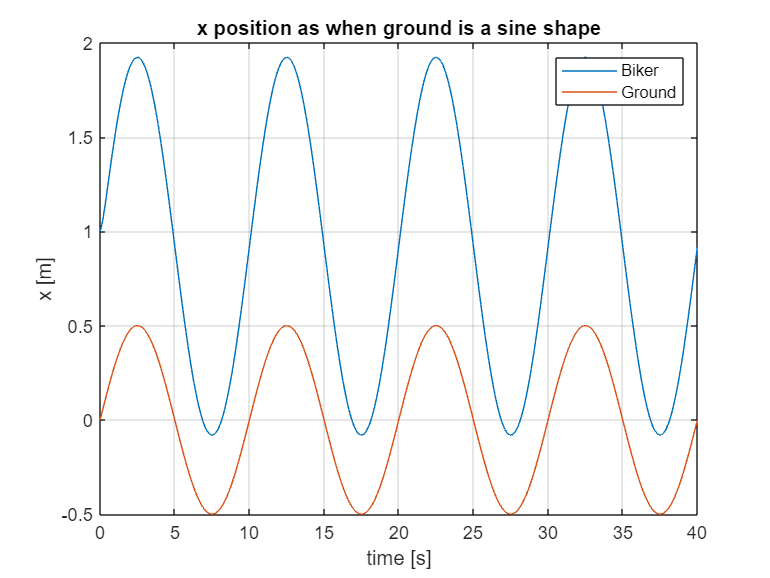


[t, X] = ode45(@odefun_step,[0 40],[0 0]);
x = -X(:,1);
v = -X(:,2); 

h0 = 0.5;
h = h0 - h0/2*heaviside(t-10)-h0/2*heaviside(t-20);

grid on

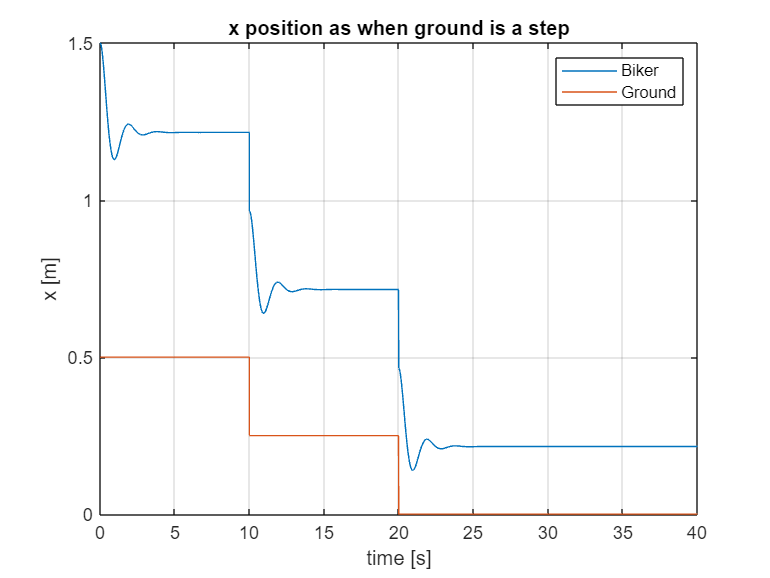

plot(t,x+h+1,t,h)
title('x position as when ground is a step')
legend('Biker','Ground')
xlabel('time [s]')
ylabel('x [m]')
grid on